close all
clear all
clc
syms l1 l2 l3  theta_1(t) theta_2(t) theta_3(t) 
xe=  l3*sin(theta_2+theta_3)*cos(theta_1) + l2*cos(theta_1)*sin(theta_2)

$$xe(t) = l_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)+l_{3}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\right)$$

ye = l3*sin(theta_2+theta_3)*sin(theta_1 ) + l2*sin(theta_1)*sin(theta_2)

$$ye(t) = l_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)+l_{3}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\right)$$

ze = l3*cos(theta_2+theta_3) + l2*cos(theta_2) + l1

$$ze(t) = l_{1}+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)+l_{3}\,\cos\left(\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\right)$$

dxe = diff(xe,t)

$$dxe(t) = \begin{array}{l} l_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)-l_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-l_{3}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+l_{3}\,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{2}\left(t\right)+\theta_{3}\left(t\right) \end{array}$$

dye = diff(ye,t)

$$dye(t) = \begin{array}{l} l_{2}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+l_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)+l_{3}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+l_{3}\,\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{2}\left(t\right)+\theta_{3}\left(t\right) \end{array}$$

dze = diff(ze,t)

$$dze(t) = -l_{3}\,\sin\left(\theta_{2}\left(t\right)+\theta_{3}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)+\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)-l_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)$$


% We have three equations and three unknowns.
% If exists, there is only one or infinite solutions.
% Due to configuration of the model, there is only one solution


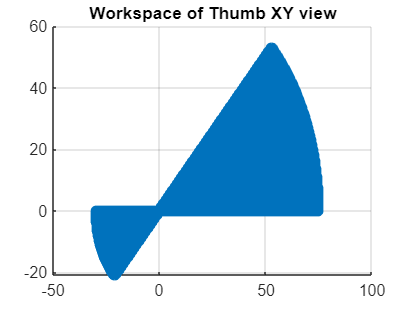

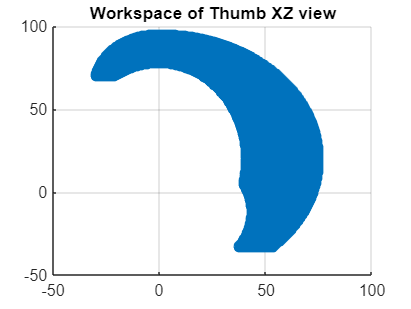

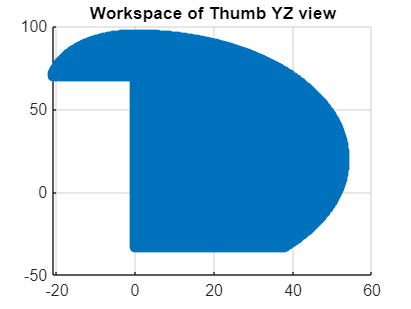

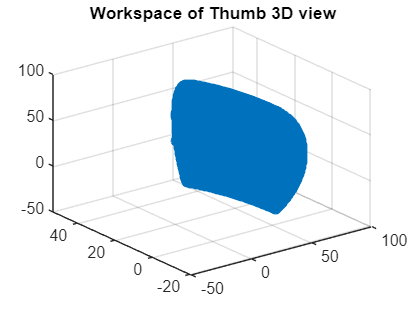

% Plot workspace
Reachableworkspace

% Find singularities
syms theta_1 theta_2 theta_3 l1 l2 l3
J=str2sym('[- l3*cos(theta_2 + theta_3)*sin(theta_1) - l2*cos(theta_2)*sin(theta_1),- l3*sin(theta_2 + theta_3)*cos(theta_1) - l2*cos(theta_1)*sin(theta_2),-l3*sin(theta_2 + theta_3)*cos(theta_1); l3*cos(theta_2 + theta_3)*cos(theta_1) + l2*cos(theta_1)*cos(theta_2),- l3*sin(theta_2 + theta_3)*sin(theta_1) - l2*sin(theta_1)*sin(theta_2),-l3*sin(theta_2 + theta_3)*sin(theta_1);0,l3*cos(theta_2 + theta_3) + l2*cos(theta_2),l3*cos(theta_2 + theta_3)]')

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{3}\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sigma_{2}-l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\sigma_{2}\\ l_{3}\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sigma_{1}-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\sigma_{1}\\ 0 & \sigma_{3}+l_{2}\,\cos\left(q_{2}\right) & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \sigma_{3}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

eqn = simplify(det(J))==0

$$eqn = -l_{2}\,l_{3}\,\left(l_{3}\,\sin\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}+l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)-l_{3}\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)=0$$


xyz=[x,y,z];
B = unique(xyz,'rows');
if length(xyz)==length(B)
    singularity=0 %there is no singularity
else
    singularity=length(xyz)-length(B) %there are singularity at infinity point. this number shows number of singularity for pre-defined angles
end

singularity = 0